# **COMPARISONS OF DIFFERENT INDEX TRACKING ALGORITHMS**

Load financial data and organize it

clear all;
ftse_matrix     = load('ftse.mat');
ftse_data       = ftse_matrix.data;
ftse_companies  = ftse_matrix.companies;
NumPorts        = 30;

Select & Build the matrix of the 30 stocks

row_size = 753;
for i = 1:NumPorts
    stock         = getfield(ftse_data, ftse_companies{i});
    ftse30(:,i)   = stock.Close(1:row_size);
end

Select the ftse index

ukx     = getfield(ftse_data, ftse_companies{31});
ftse100 = ukx.Close(1:row_size);

% Reorder the data % Reverse the data according to earliest date

ftse30  = ftse30(end:-1:1, :);
ftse100 = ftse100(end:-1:1, :);

**Return** 

Calculate Daily Return

ftse30_return  = price2ret(ftse30);
ftse100_return = price2ret(ftse100);

**Expected Returns and Covariances**

ERet30  = mean(ftse30_return)';
ECov30  = cov(ftse30_return);
ERet100 = mean(ftse100_return)';
ECov100 = cov(ftse100_return);

**Index Tracking** :- 

Greedy selection

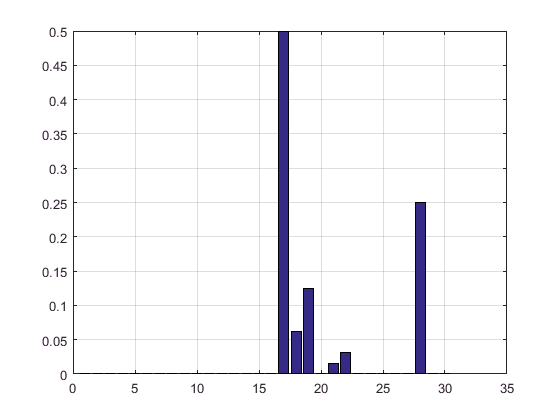


y   = ftse100_return;
R   = ftse30_return;
wt  = zeros(NumPorts,1);
for i = 1:6
    v = 1/(2^i);
    
    % set the values of some spare portfolio
    for j = 1:NumPorts
        if(wt(j) >= v)
            %wt(j) = v;
        end
    end
    
    % greedy selection
    for k=1:NumPorts
        if(wt(k) == 0)
            wt(k) = v;
            track(k) = norm(y - R*wt);
            wt(k) = 0;
        else
            track(k) = norm(y - R*wt);
        end
    end
    
    % pick the minimum
    mini = inf;
    t_index = 1;
    for p = 1:NumPorts
        if(track(p) < mini)
            mini = track(p);
            t_index = p;
        end
    end
    wt(t_index) = v;
end
ww1 = wt;
figure; clf, bar(wt); grid on; %xlabel(ftse_companies(:))


R   = ftse30_return;
f   = ftse100_return;
S = [];
weight = [];

Co = 6; N = 30;
    k = 1;
    min_err = 10000;
    for k = 1: Co
        i = 1;
        for j = 1:N
            if(~ismember(j, S))
                % Using CVX to get the optimal weight                              
                R_co = ([ R(:, [S]),  R(:, j) ]);                
                w_co = computeWeight(f, R_co);    % compute weight vector
                Ret_err = norm(f -  (R_co * w_co));
                if(Ret_err < min_err)
                    opt_w = w_co;
                    stock = j;
                end
            end
        end
        weight =  opt_w;
        S = [S, stock];
%         k = k+1;
%         min_err = min(Ret_err);
%         [r, c] = find( w_track == min_err );
        
%         % find the minimum
%         for i = 1: size(w_co_vector)            
%             Ret_err = f * w_co_vectors;
%             if(Ret_err < err)
%                 err = Ret_err;
%                 new_w =
        
%         w = [w w_];
    end


 Greedy selection Naive equal weight selection

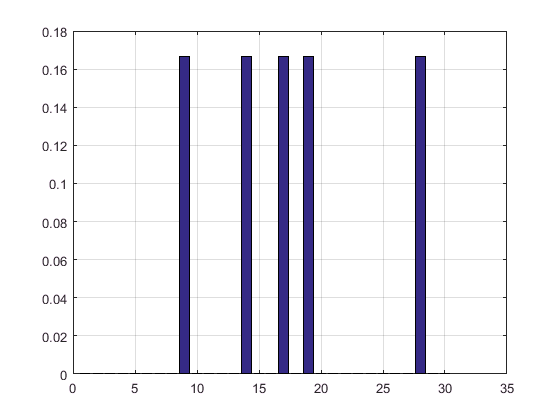

y   = ftse100_return;
R   = ftse30_return;
wt  = zeros(NumPorts,1);
for i = 1:6
    v = 1/i;
    
    % set the values of some spare portfolio
    for j = 1:NumPorts
        if(wt(j) >= v)
            wt(j) = v;
        end
    end
    
    % greedy selection
    for k=1:NumPorts
        if(wt(k) == 0)
            wt(k) = v;
            track(k) = norm(y - R*wt);
            wt(k) = 0;
        else
            track(k) = norm(y - R*wt);
        end
    end
    
    % pick the minimum
    mini = inf;
    t_index = 1;
    for p = 1:NumPorts
        if(track(p) < mini)
            mini = track(p);
            t_index = p;
        end
    end
    wt(t_index) = v;
end
ww2 = wt;
figure; clf, bar(wt); grid on; %xlabel(ftse_companies(:))

## **Sparse Index Tracking **

Using CVX to get the optimal weight

[T, N]  = size(ftse30_return);
% rho     = 0.2786;
R       = ftse30_return;
tau     = 427;
mu      = ERet30(:);       % Ensuring its column vector
y       = ftse100_return;

cvx_begin quiet
    variable w2(N);
    minimize( norm(y - R*w2, 2)  +  (tau * norm(w2,1)));
    subject to
        w2' * ones(N,1) == 1
       %w2              >= 0
        nnz(w2) <= 6;
cvx_end
 w2(w2>0)

ans =     0.0187
    0.0240
    0.0230
    0.0000
    0.0138
    0.0172
    0.0082
    0.0431
    0.0625
    0.0010


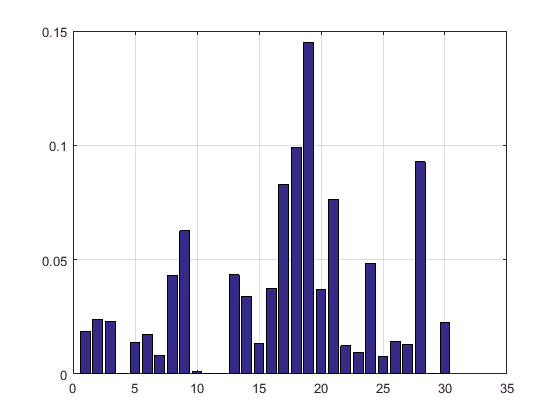

% sum(w2)
figure; clf, bar(w2); grid on; %xlabel({ftse_companies})